imds = imageDatastore('C:\Users\Shreyas Desai\Desktop\test\ResizedDataset', 'LabelSource', 'foldernames', 'IncludeSubfolders',true);

Step 1

tbl = countEachLabel(imds)

tbl = 4×2 table
        Label         Count
    ______________    _____

    resize_comedy      100 
    resized_anime      100 
    resized_horror      99 
    resized_scifi       93 


Step 2

% Determine the smallest amount of images in a category
minSetCount = min(tbl{:,2}); 

% Limit the number of images to reduce the time it takes
% run this example.
maxNumImages = 100;
minSetCount = min(maxNumImages,minSetCount);

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 4×2 table
        Label         Count
    ______________    _____

    resize_comedy      93  
    resized_anime      93  
    resized_horror     93  
    resized_scifi      93  


Step 3

% Load pretrained network
net = resnet50();

Step 4 

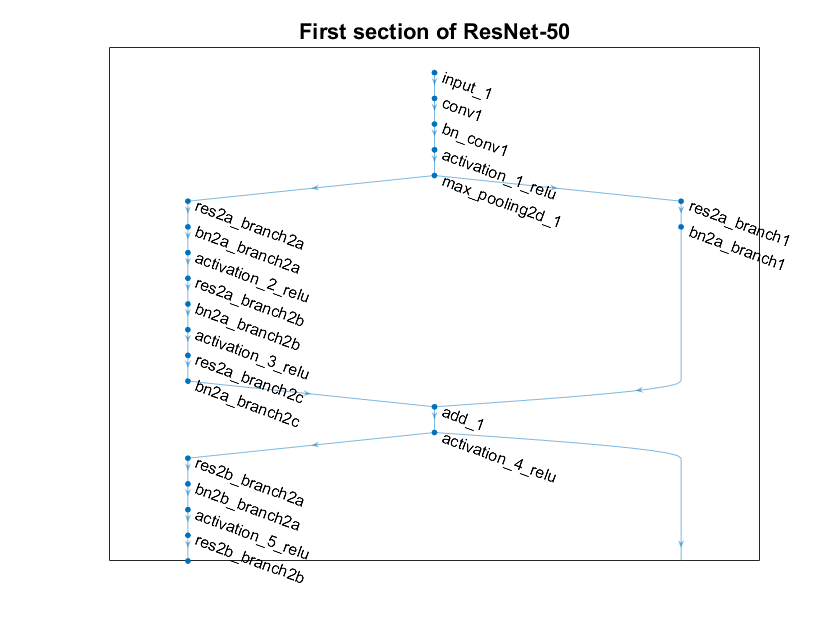

% Visualize the first section of the network. 
figure
plot(net)
title('First section of ResNet-50')
set(gca,'YLim',[150 170]);

Step 5

% Inspect the first layer
net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input_1'
                 InputSize: [224 224 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


Step 6

% Inspect the last layer
net.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'ClassificationLayer_fc1000'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


Step 7

% Number of class names for ImageNet classification task
numel(net.Layers(end).ClassNames)

ans = 1000

Step 8

[trainingSet, testSet] = splitEachLabel(imds, 0.3, 'randomize');

Step 9

% Create augmentedImageDatastore from training and test sets to resize
% images in imds to the size required by the network.
imageSize = net.Layers(1).InputSize;
augmentedTrainingSet = augmentedImageDatastore(imageSize, trainingSet, 'ColorPreprocessing', 'gray2rgb');
augmentedTestSet = augmentedImageDatastore(imageSize, testSet, 'ColorPreprocessing', 'gray2rgb');

Step 10

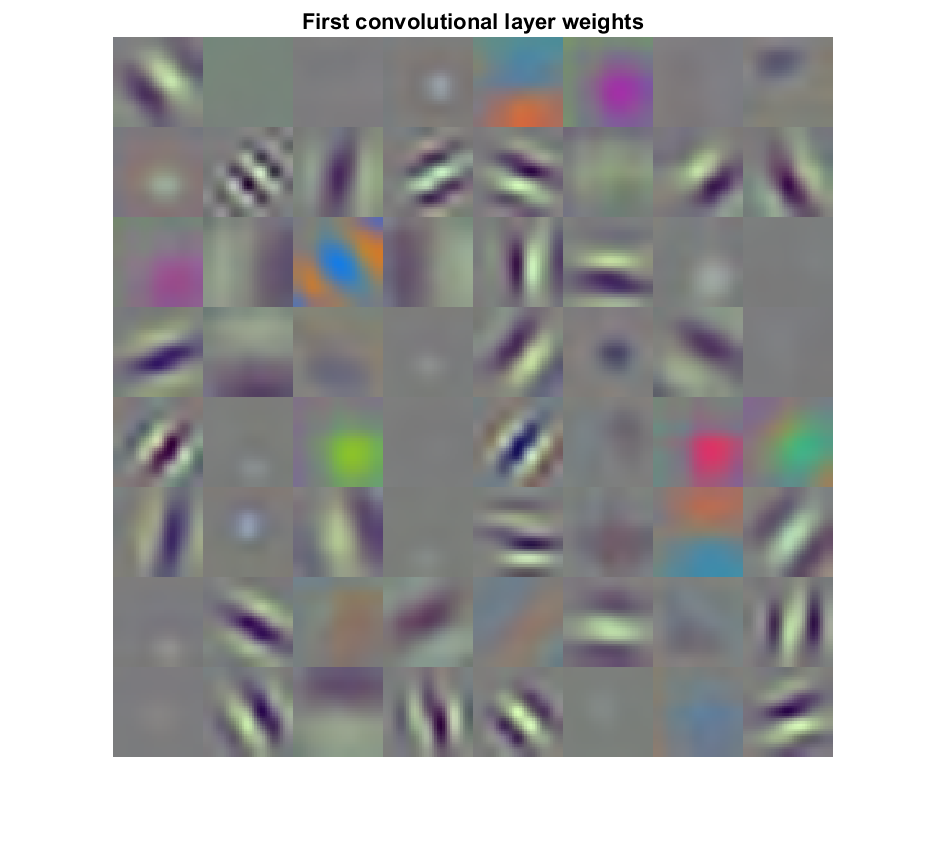

% Get the network weights for the second convolutional layer
w1 = net.Layers(2).Weights;

% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5); 

% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w1)
title('First convolutional layer weights')

Step 11

featureLayer = 'fc1000';
trainingFeatures = activations(net, augmentedTrainingSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

Step 12

% Get training labels from the trainingSet
trainingLabels = trainingSet.Labels;

% Train multiclass SVM classifier using a fast linear solver, and set
% 'ObservationsIn' to 'columns' to match the arrangement used for training
% features.
classifier = fitcecoc(trainingFeatures, trainingLabels, ...
    'Learners', 'Linear', 'Coding', 'onevsall', 'ObservationsIn', 'columns');

Step 13

% Extract test features using the CNN
testFeatures = activations(net, augmentedTestSet, featureLayer, ...
    'MiniBatchSize', 32, 'OutputAs', 'columns');

% Pass CNN image features to trained classifier
predictedLabels = predict(classifier, testFeatures, 'ObservationsIn', 'columns');

% Get the known labels
testLabels = testSet.Labels;

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels);

% Convert confusion matrix into percentage form
confMat = bsxfun(@rdivide,confMat,sum(confMat,2))

confMat =     0.8000    0.0462    0.1385    0.0154
    0.0615    0.8308    0.0462    0.0615
    0.0615    0.0154    0.7692    0.1538
    0.0154    0.1385    0.2154    0.6308


Step 14

% Display the mean accuracy
mean(diag(confMat))

ans = 0.7577

Step 15

testImage = readimage('uri','jpg');

Check for missing argument or incorrect argument data type in call to function 'readimage'.

testLabel = testSet.Labels(1)

Step 16

% Create augmentedImageDatastore to automatically resize the image when
% image features are extracted using activations.
ds = augmentedImageDatastore(imageSize, testImage, 'ColorPreprocessing', 'gray2rgb');

% Extract image features using the CNN
imageFeatures = activations(net, ds, featureLayer, 'OutputAs', 'columns');

Step 17


% Make a prediction using the classifier
predictedLabel = predict(classifier, imageFeatures, 'ObservationsIn', 'columns')